# Constrained Polynomial Approximation (2D)

Course: Data Science for Engineers II

Date: 17.12.2024

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load dataset

The data is stored in a csv file titled SingleCell_D.csv.

allData = readmatrix('SingleCell_D.csv');

In it, each row contains 30 numbers, which are the sensor values from the $6 \times 5$ grid. So the columns are the different sensors, and the rows are the different times. In the beginning, there was no external pressure on the sensors. After a while, external pressure was applied to a single cell somewhere in the middle. Let's try and find out which row has a data where this middle cell is pressed.

[maxVal, idx] = max(allData);

The maxVal variable contains the maxima for each column. 

We can plot it, to see that one column has a much higher maximum than the rest. 

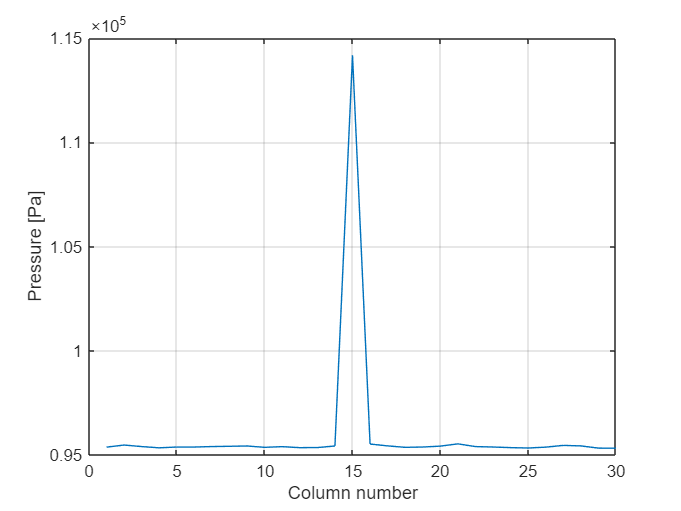

figure;
plot(maxVal);
grid on;
xlabel('Column number');
ylabel('Pressure [Pa]');

So, if we find the peak in that graph, we will see which column has the pressed cell. 

[~, colMax] = max(maxVal);

On the other hand, the variable idx from line 4 contains the indices of the maxima in each column. So it tells us, in which **row **is the maximum in that particular column.

rowMax = idx(colMax);

According to these calculations, the maximum element in the matrix is in the 270th row, so that is the one we will take a closer look at.

## Extract data

The second row in the matrix contains the value from the sensors with no external pressure (other than the atmospheric pressure). We can use these as a baseline to subtract, so that our values are "zeroed" and we don't have to deal with large numbers. 

rowData = allData(rowMax, :) - allData(2, :);
rowData = rowData./max(max(rowData));

Next, we will convert the data from a row to a $6 \times 5$ matrix corresponding to the grid.

nrSensorHor = 5;
nrSensorVer = 6;
sensorData = reshape(rowData, nrSensorVer, nrSensorHor);

We can now visualize the raw sensor data from that row to see if it looks like what we expect it to,

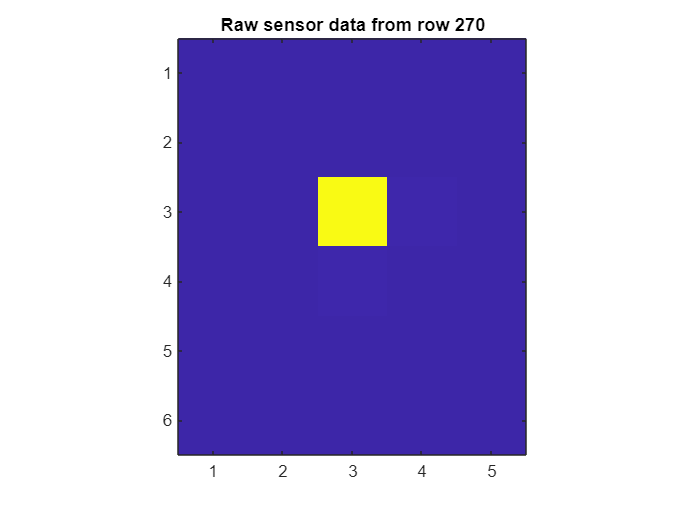

figure
imagesc(sensorData);
axis image;
title(['Raw sensor data from row ', num2str(rowMax)]);

We can see that the raw data looks like what we expect, so we have done things correctly until now.

## Perform unconstrained interpolation

Let's see what an unconstrained polynomial surface would look like. For easy computations, we will deifne the$x$ and$y$ values on the interval $\left\lbrack -1,1\right\rbrack$.

degX = size(sensorData, 2) - 1;
degY = size(sensorData, 1) - 1;
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Now we can define the Vandermonde matrices

Vx = vander(x);
Vy = vander(y);

Perform unconstrained polynomial interpolation

uncCoeffs = pinv(Vy)*sensorData*pinv(Vx');

## Visualize the unconstrained interpolation

Because we have more sensors vertically than horizontally, I will accordingly define an appropriate number of points for visualization in both directions.

factor = 20;
xPlot = linspace(-1, 1, factor*nrSensorHor);
yPlot = linspace(-1, 1, factor*nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);
%
interpSurface = VyPlot*uncCoeffs*VxPlot';

In order to visualize the interpolating surface, we will use the *imagesc* function, as well as the *surf* function.

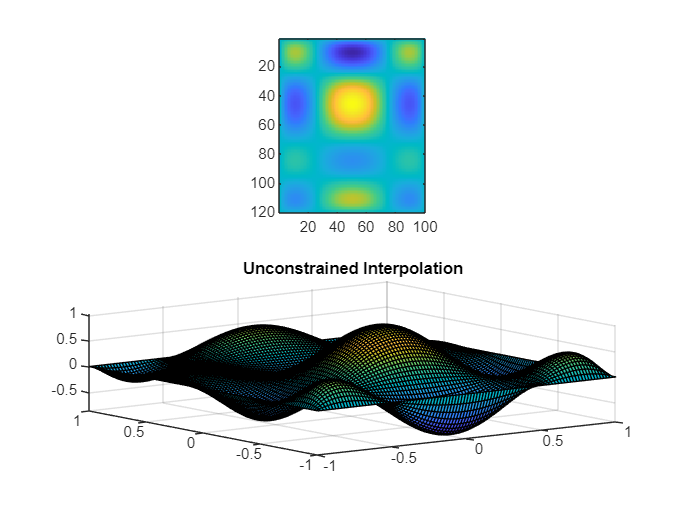

figure
subplot(2,1,1)
imagesc(interpSurface);
axis image;
subplot(2,1,2)
[xSurf, ySurf] = meshgrid(xPlot, yPlot);
surf(xSurf, ySurf, interpSurface);
title('Unconstrained Interpolation');

As we can see, in this case unconstrained interpolation doesn't provide good results due to the Runge phenomenon. Let's try and introduce some constraints.

## Adding value constraints

In this case, we can add both value and derivative constraints.

First, let's add value constraints on the first and last row, making sure those values are zero.

Set up constraints matrices

Cx = Vx;
Cy = Vy([1, end], :);
%
kronP = kron(Cx, Cy);
N = null(kronP);

Compute the coefficients

vecCoeffs = N*pinv(kron(Vx, Vy)*N)*sensorData(:);
valConCoeffs = reshape(vecCoeffs, degY + 1, degX + 1);

Plot the surface

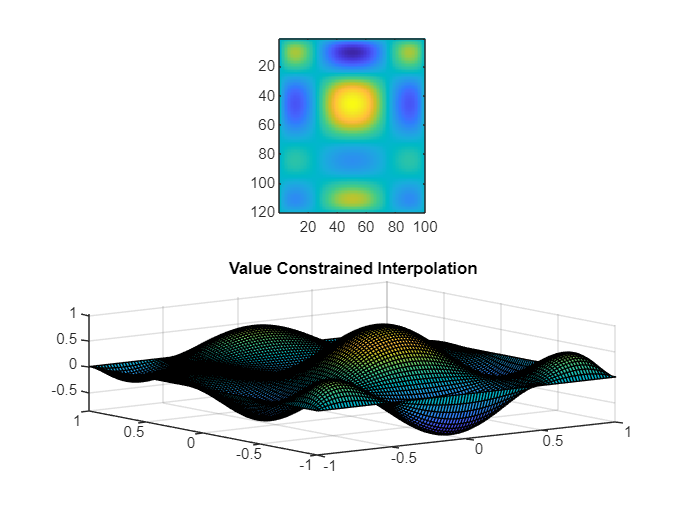

interpSurfaceVC = VyPlot*valConCoeffs*VxPlot';
figure
subplot(2,1,1)
imagesc(interpSurfaceVC);
axis image;
subplot(2,1,2)
surf(xSurf, ySurf, interpSurfaceVC);
title('Value Constrained Interpolation');

The value constraints don't change much, since the surface was already almost zero at the edges. We can see this visually, or by comparing the coefficients or even the interpolating surfaces themselves.

## Adding derivative constraints

We will add derivative constraints on top of the value constraints.

First we need to define the derivative matrices

Dx = diag(degX:-1:1, -1);
Dy = diag(degY:-1:1, -1);
derVanX = Vx*Dx;
derVanY = Vy*Dy;

Now we need to define the constraint matrices with just the derivative constraints.

Cdx = derVanX;
Cdy = derVanY([1, end], :);

We will incorporate the value AND derivative constraints

Cx = [Cx; Cdx];
Cy = [Cy; Cdy];
kronP = kron(Cx, Cy);
dN = null(kronP);

Compute the coefficients

vecCoeffsDer = dN*pinv(kron(Vx, Vy)*dN)*sensorData(:);
valConCoeffs = reshape(vecCoeffsDer, degY + 1, degX + 1);

Plot the surface

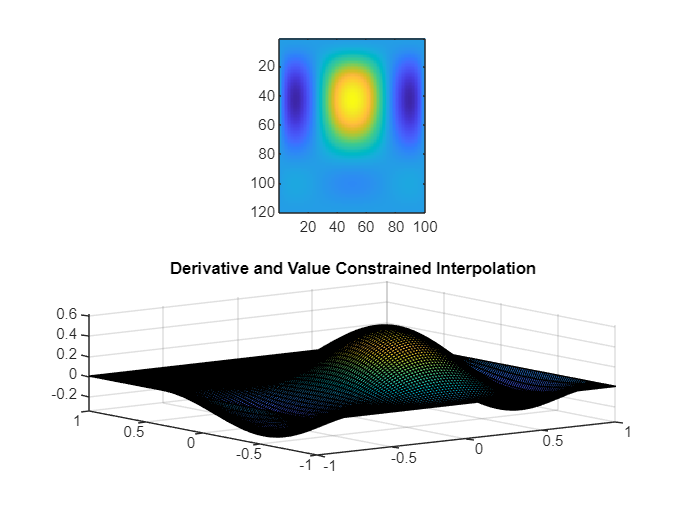

interpSurfaceDVC = VyPlot*valConCoeffs*VxPlot';
figure
subplot(2,1,1)
imagesc(interpSurfaceDVC);
axis image;
subplot(2,1,2)
surf(xSurf, ySurf, interpSurfaceDVC);
title('Derivative and Value Constrained Interpolation');